# Notas de clase: Sistemas Lineales

## Clase 1: Presentación del curso

## Clase 2: Repaso de ecuaciones diferenciales ordinarias

clear,clc

### Definiciones

- **Ecuación diferencial: **Ecuación que contiene derivadas

- **Ecuación diferenciales ordinarias: **Aplicación de las ecuaciones diferenciales a sistemas donde los parámetros son concentrados (todas las propiedades del sistema se resumen a un punto, es decir, se minimizan las variables independientes necesarias). **Ejemplo: **$f\left(t,y,\overset{\ldotp }{y} ,\overset{\ldotp \ldotp }{y} ,\ldotp \ldotp \ldotp ,\overset{\left(n\right)}{y} \right)=0,\;\;\;\;\overset{\ldotp }{y} =\frac{\mathrm{d}}{\textrm{d}t}y$

- **Ecuaciones diferenciales parciales: **Aplicación a sistemas con parámetros distribuidos (las propiedades del sistema requieren más de una variable para expresarse)

- **Ecuaciones lineales: **Se dice que una ecuación diferencial de n-ésimo orden es lineal si $f\left(t,y,\overset{\ldotp }{y} ,\overset{\ldotp \ldotp }{y} ,\ldotp \ldotp \ldotp ,\overset{\left(n\right)}{y} \right)$ es lineal en $y,\overset{\ldotp }{y} ,\overset{\ldotp \ldotp }{y} ,\ldotp \ldotp \ldotp ,\overset{\left(n\right)}{y}$. Dicho de otra forma, la ecuación diferencial de n-ésimo orden es lineal si tiene la forma $a_n \left(t\right)\overset{\left(n\right)}{y} +\ldotp \ldotp \ldotp +a_0 \left(t\right)y=u\left(t\right)$.

- **Ecuaciones lineales con coeficientes constantes: **Se les conoce como **LTI **(Linear-Time-Invariant). Los coeficientes que acompañan a la variable dependiente no cambian con el tiempo, por tanto, son de la forma $a_n \overset{\left(n\right)}{y} +\ldotp \ldotp \ldotp +a_0 y=u\left(t\right)\ldotp$ Existen métodos analíticos para resolver estas ecuaciones. El término $u\left(t\right)$tiene significado como la entrada del sistema.

- **Problema de valor inicial: **Es un problema de la forma $\left\lbrace \begin{array}{ll}
\overset{\left(n\right)}{y} +a_1 \overset{\left(n-1\right)}{y} +\ldotp \ldotp \ldotp +a_n y=u\left(t\right) & \\
y\left(0\right)=y_{01} ,\ldotp \ldotp \ldotp ,\overset{\left(n-1\right)}{y\left(0\right)} =y_{0n}  & 
\end{array}\right.$

- **Solución general de un problema de valor inicial: **Se calcula la solución general como la suma de la solución de la ecuación complementaria homogénea ($y_c$) y una solución particular de la ecuación no homogénea ($y_p$). De forma tal, la solución general viene dada por $y\left(t\right)=y_c \left(t\right)+y_p \left(t\right)$.

- **Solución **$y_c \left(t\right)$**de la ecuación homogénea **($u\left(t\right)=0$)**: **Se obtiene el polinomio característico y se resuelve para obtener los valores característicos. Debe lidiarse con los casos de valores característicos reales diferentes, complejos diferentes y raíces múltiples. El polinomio característico de $\overset{\left(n\right)}{y} +a_1 \overset{\left(n-1\right)}{y} +\ldotp \ldotp \ldotp +a_n y=u\left(t\right)$ es de la forma $\lambda^n +a_1 \lambda^{n-1} +\ldotp \ldotp \ldotp +a_{n-1} \lambda +a_n =0$.

- **Solución **$y_p \left(t\right)$**de la ecuación no homogénea: **Se puede resolver aplicando el método de coeficientes indeterminados (método especial pero simple) o el método de variación de parámetros (método general pero complejo). Para ambos métodos consultar el libro de [Dennis G. Zill & Warren S. Wright](https://www.booksfree.org/differential-equation-by-dennis-g-zill/).

### Ejemplos

#### 1) La ecuación diferencial como definición de un campo vectorial

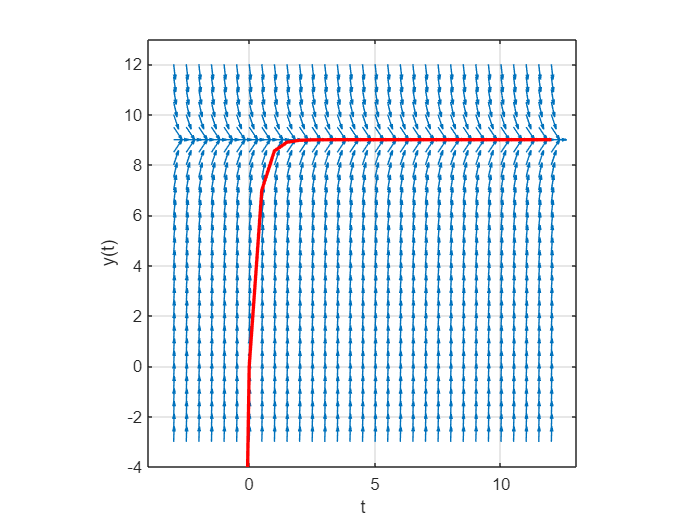

t=-3:0.5:12; y=-3:0.5:12; % define grid of values in t and y directions
[T,Y]=meshgrid(t,y); % creates 2d matrices
dT=ones(size(T)); % dt=1 for all points
dY=27-3*Y; % dy=(t^2-y)*dt: this is the ODE
N=sqrt(dT.^2+dY.^2); % magnitude of arrows
dT=dT./N; % normalize arrows to get all same length
dY=dY./N;
figure(1)
clf
quiver(T,Y,dT,dY) % draw arrows (t,y) --> (t+dt,y+dy)
axis equal
axis([-4 13 -4 13]) % repeat adjustments...
grid on
hold on
C1=9;
y=9-C1*exp(-3*t);
plot(t,y,'r','LineWidth',2);
hold off
xlabel('t')
ylabel('y(t)')

#### 2) Solución de ecuación homogénea

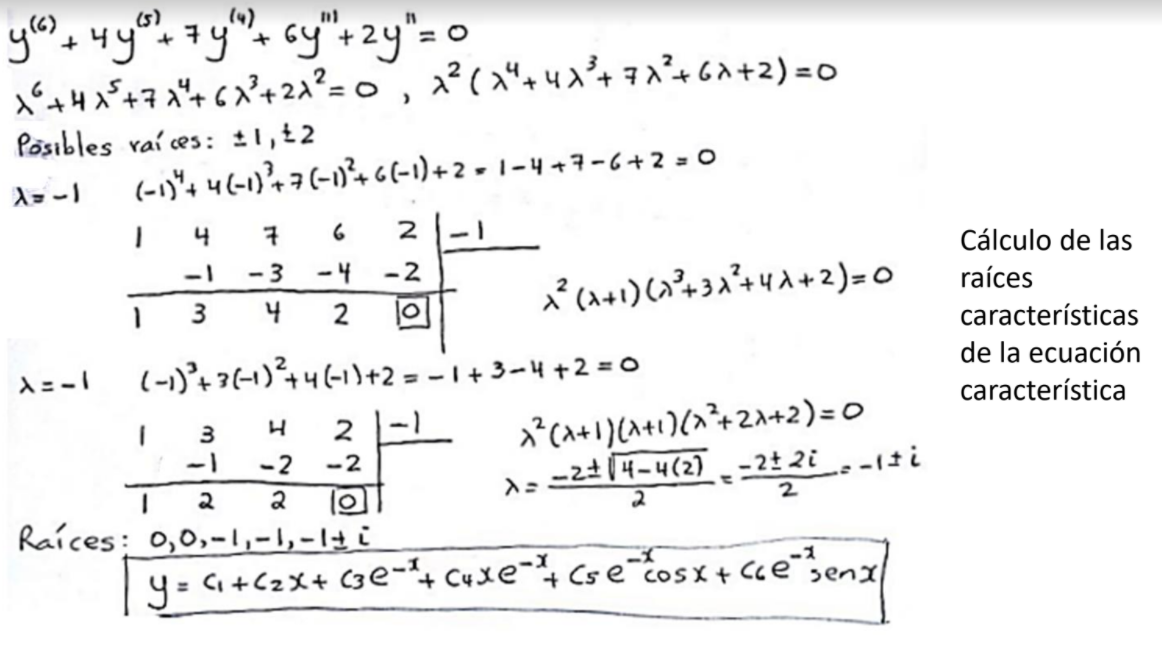

**Comprobación de la solución en MatLab**

syms y(x)
ode=diff(y,6)+4*diff(y,5)+7*diff(y,4)+6*diff(y,3)+2*diff(y,2)==0

$$ode(x) = \frac{\partial^{6}}{\partial x^{6}}y\left(x\right)+4\,\frac{\partial^{5}}{\partial x^{5}}y\left(x\right)+7\,\frac{\partial^{4}}{\partial x^{4}}y\left(x\right)+6\,\frac{\partial^{3}}{\partial x^{3}}y\left(x\right)+2\,\frac{\partial^{2}}{\partial x^{2}}y\left(x\right)=0$$

ySol(x) = dsolve(ode)

$$ySol(x) = C_{2}-\frac{3\,C_{1}}{2}+\frac{C_{1}\,x}{2}+C_{3}\,{\mathrm{e}}^{-x}+C_{4}\,x\,{\mathrm{e}}^{-x}+C_{5}\,{\mathrm{e}}^{-x}\,\cos\left(x\right)-C_{6}\,{\mathrm{e}}^{-x}\,\sin\left(x\right)$$

#### 3) Solución de ecuación no homogénea

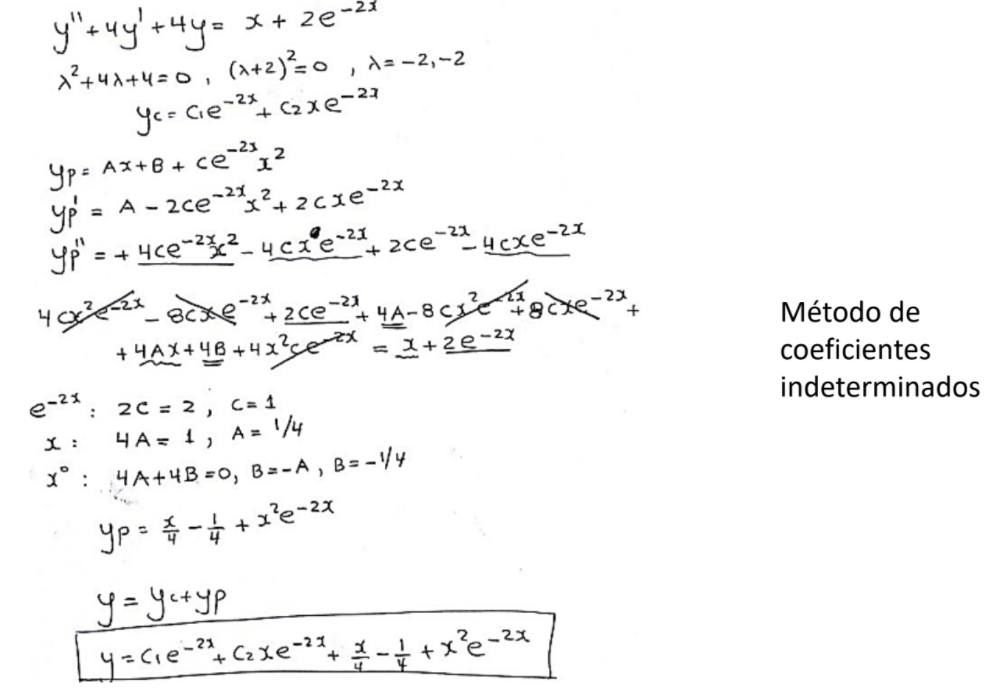

**Comprobación de la solución en MatLab**

ode2=diff(y,2)+4*diff(y)+4*y==x+2*exp(-2*x)

$$ode2(x) = \frac{\partial^{2}}{\partial x^{2}}y\left(x\right)+4\,\frac{\partial }{\partial x}y\left(x\right)+4\,y\left(x\right)=x+2\,{\mathrm{e}}^{-2\,x}$$

ySol2(x) = simplify(dsolve(ode2))

$$ySol2(x) = \frac{x}{4}+x^{2}\,{\mathrm{e}}^{-2\,x}+C_{1}\,{\mathrm{e}}^{-2\,x}+C_{2}\,x\,{\mathrm{e}}^{-2\,x}-\frac{1}{4}$$

## Clase 3: Ecuaciones en diferencias

clear;clc

### Definiciones

- **Ecuación en diferencias: **Es una ecuación que contiene diferencias ($\Delta$).

- **Diferencias hacia adelante: **$\Delta y\left(kT\right)=\frac{y\left(\left(k+1\right)T\right)-y\left(kT\right)}{T}$,  $\overset{\left(2\right)}{\Delta} y\left(kT\right)=\frac{\Delta y\left(\left(k+1\right)T\right)-\Delta y\left(kT\right)}{T}=\frac{y\left(\left(k+2\right)T\right)-2y\left(\left(k+1\right)T\right)+y\left(kT\right)}{T^2 }$

- **Diferencias hacia atrás: **$\Delta y\left(kT\right)=\frac{y\left(kT\right)-y\left(\left(k-1\right)T\right)}{T}$,  $\overset{\left(2\right)}{\Delta} y\left(kT\right)=\frac{\Delta y\left(kT\right)-\Delta y\left(\left(k-1\right)T\right)}{T}=\frac{y\left(kT\right)-2y\left(\left(k-1\right)T\right)+y\left(\left(k-2\right)T\right)}{T^2 }$

- **Forma canónica de una ecuación en diferencias hacia adelante: **Se obtiene luego de simplificar $\Delta$ y reemplazar $T$, $\left\lbrace \begin{array}{ll}
y\left(k+n\right)+a_1 y\left(k+n-1\right)+\ldotp \ldotp \ldotp +a_n y\left(k\right)=u\left(k\right) & \\
y\left(0\right)=y_{01} ,y\left(1\right)=y_{02} ,\ldotp \ldotp \ldotp ,y\left(n-1\right)=y_{0n}  & 
\end{array}\right.$

- **Forma canónica de una ecuación en diferencias hacia atrás: **Se obtiene luego de simplificar $\Delta$ y reemplazar $T$, $\left\lbrace \begin{array}{ll}
y\left(k\right)+a_1 y\left(k-1\right)+\ldotp \ldotp \ldotp +a_n y\left(k-n\right)=u\left(k\right) & \\
y\left(0\right)=y_{01} ,y\left(-1\right)=y_{02} ,\ldotp \ldotp \ldotp ,y\left(-n\right)=y_{0n}  & 
\end{array}\right.$

### Ecuación en diferencias a partir de una ecuación diferencial:

Supongamos que deseamos discretizar la ecuación $\frac{d}{\textrm{d}t}y+ay=u\left(t\right),y\left(0\right)=y_0$, para ello debemos notar que $\frac{d}{\textrm{d}t}y\simeq \frac{y\left(k\right)-y\left(k-1\right)}{T}$ (diferencias hacia atrás) y por ende podemos reescribir la ecuación como $\frac{y\left(k\right)-y\left(k-1\right)}{T}+ay\left(k-1\right)=u\left(k-1\right)\Longrightarrow y\left(k\right)+\left(aT-1\right)y\left(k-1\right)=Tu\left(k-1\right)$, de forma tal, el problema original se convierte en $\left\lbrace \begin{array}{ll}
y\left(k\right)=\left(1-aT\right)y\left(k-1\right)+Tu\left(k-1\right) & \\
y\left(0\right)=y_0  & 
\end{array}\right.$

#### Ejemplo: Ecuación en diferencias hacia atrás de orden 2

Resolver la ecuación en diferencias dada por $\left\lbrace \begin{array}{ll}
y\left(k\right)+0\ldotp 9y\left(k-1\right)+0\ldotp 14y\left(k-2\right)=0\ldotp 3u\left(k-1\right)-0\ldotp 6u\left(k-2\right), & u\left(k\right)=\delta \left(k-1\right)=\left\lbrace \begin{array}{ll}
1 & k=1\\
0 & k\not= 1
\end{array}\right.\\
y\left(0\right)=y\left(1\right)=0 & 
\end{array}\right.$

Solucionamos aprovechando la relación de recurrencia:


$$\begin{array}{l}
y\left(k\right)=-0\ldotp 9y\left(k-1\right)-0\ldotp 14y\left(k-2\right)+0\ldotp 3\delta \left(k-2\right)-0\ldotp 6\delta \left(k-3\right)\\
y\left(2\right)=-0\ldotp 9y\left(1\right)-0\ldotp 14y\left(0\right)+0\ldotp 3\delta \left(0\right)-0\ldotp 6\delta \left(-1\right)=0\ldotp 3\\
y\left(3\right)=-0\ldotp 9y\left(2\right)-0\ldotp 14y\left(1\right)+0\ldotp 3\delta \left(1\right)-0\ldotp 6\delta \left(0\right)=-0\ldotp 9\left(0\ldotp 3\right)-0\ldotp 6=-0\ldotp 87\\
\vdots 
\end{array}$$


**Nota: **Es posible utilizar más de un método de discretización para aproximar las derivada, por ejemplo el método de Runge-Kutta4 o el método de Heun.

#### Comparación entre solución discretizada y la solución de la ecuación diferencial discretizada

Supongamos que tenemos la ecuación $\frac{d}{\mathrm{d}t}y+\mathrm{ay}=e^{-t} ,\;y\left(0\right)=2$, al discretizar con $T$ llegamos a la expresión $\left\lbrace \begin{array}{ll}
y\left(k\right)=\left(1-aT\right)y\left(k-1\right)+{Te}^{-T\left(k-1\right)}  & \\
y\left(0\right)=y_o  & 
\end{array}\right.$. Para resolver esta ecuación en el intervalo $\left\lbrack 0\;,10\right\rbrack$ podemos implementar el siguiente código

T=0.16;
a=1;
y_0=-4;
time=0:T:10;

%%%% Solución continua
syms y(t)
ode = diff(y)+a*y-exp(-t)==0

$$ode(t) = \frac{\partial }{\partial t}y\left(t\right)-{\mathrm{e}}^{-t}+y\left(t\right)=0$$

cond = y(0)==y_0;
ySol(t)=dsolve(ode,cond)

$$ySol(t) = {\mathrm{e}}^{-t}\,\left(t-4\right)$$

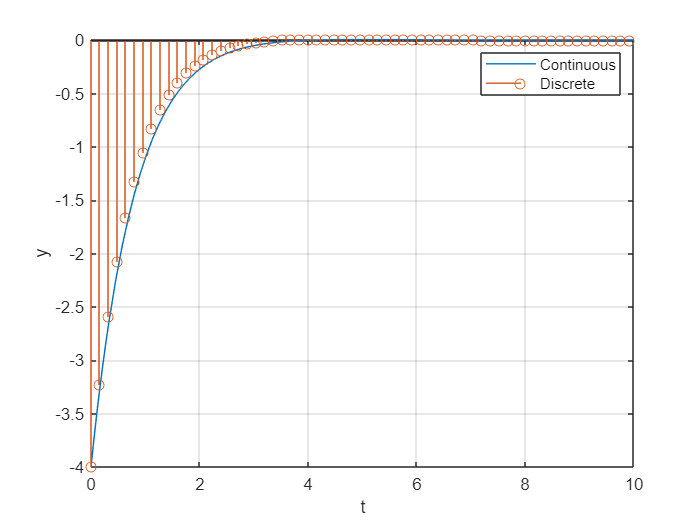


%%%% Solución discreta
yDis=t;
yCont=yDis;
yDis(1)=y_0;
for k=[1:length(time)-1]+1
    yDis(k)=(1-a*T)*yDis(k-1)+T*exp(-T*(k-1));
end
figure(1)
clf
fplot(ySol,[0 10])
grid on
hold on
stem(time,vpa(yDis))
xlabel('t')
ylabel('y')
legend({'Continuous','Discrete'})

#### T implícito vs T explícito

Una vez se ha obtenido la ecuación en diferencias a partir de la ecuación diferencial es posible omitir el instante en el tiempo y concentrarse solo en el número de muestreo actual (T implícito). Para graficar adecuadamente es necesario recordar que $t=kT$.

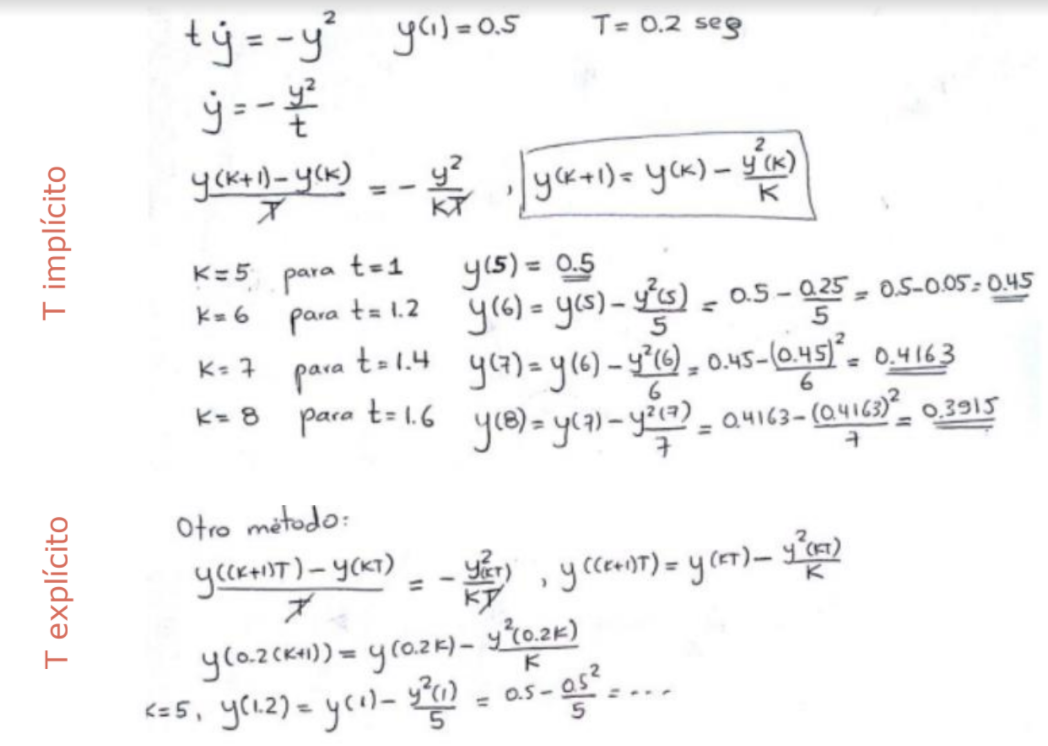

### Solución analítica de una ecuación en diferencias

De la misma forma que se pueden solucionar las ecuaciones diferenciales LTI, es posible plantear un problema de autovalores para las ecuaciones en diferencias. Sea tal solución $\phi =e^{\gamma k}$, reemplazamos en la ecuación en diferencias  $y\left(k+n\right)+a_1 y\left(k+n-1\right)+\ldotp \ldotp \ldotp +a_n y\left(k\right)=0$ para obtener $e^{\gamma \left(k+n\right)} +a_1 e^{\gamma \left(k+n-1\right)} +\ldotp \ldotp \ldotp +a_n e^{\gamma k} =0\Longrightarrow e^{\gamma k} \left(e^{\gamma n} +a_1 e^{\gamma \left(n-1\right)} +\ldotp \ldotp \ldotp +a_n \right)=0$, ahora, introduciendo el cambio de variable $\lambda =e^{\gamma }$ tenemos que $e^{\gamma k} \left(e^{\gamma n} +a_1 e^{\gamma \left(n-1\right)} +\ldotp \ldotp \ldotp +a_n \right)=\lambda^k \left(\lambda^n +a_1 \lambda^{n-1} +\ldotp \ldotp \ldotp +a_n \right)=0\Longrightarrow \lambda^n +a_1 \lambda^{n-1} +\ldotp \ldotp \ldotp +a_n =0$, lo cual se cumplirá para $\lambda \in \left\lbrace \lambda_1 ,\ldotp \ldotp \ldotp ,\lambda_n \right\rbrace$. Resta notar entonces que $\phi =e^{\gamma k} =\lambda^k$ para encontrar las soluciones de la ecuación.

#### Primer ejemplo de solución analítica

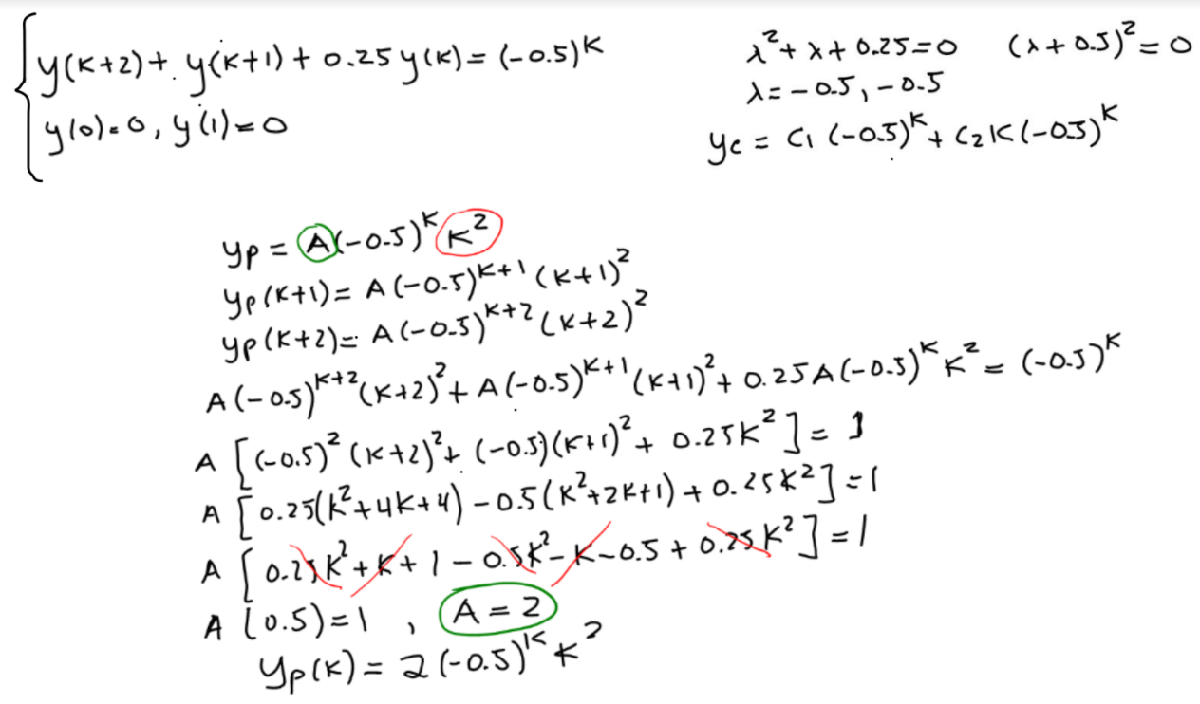

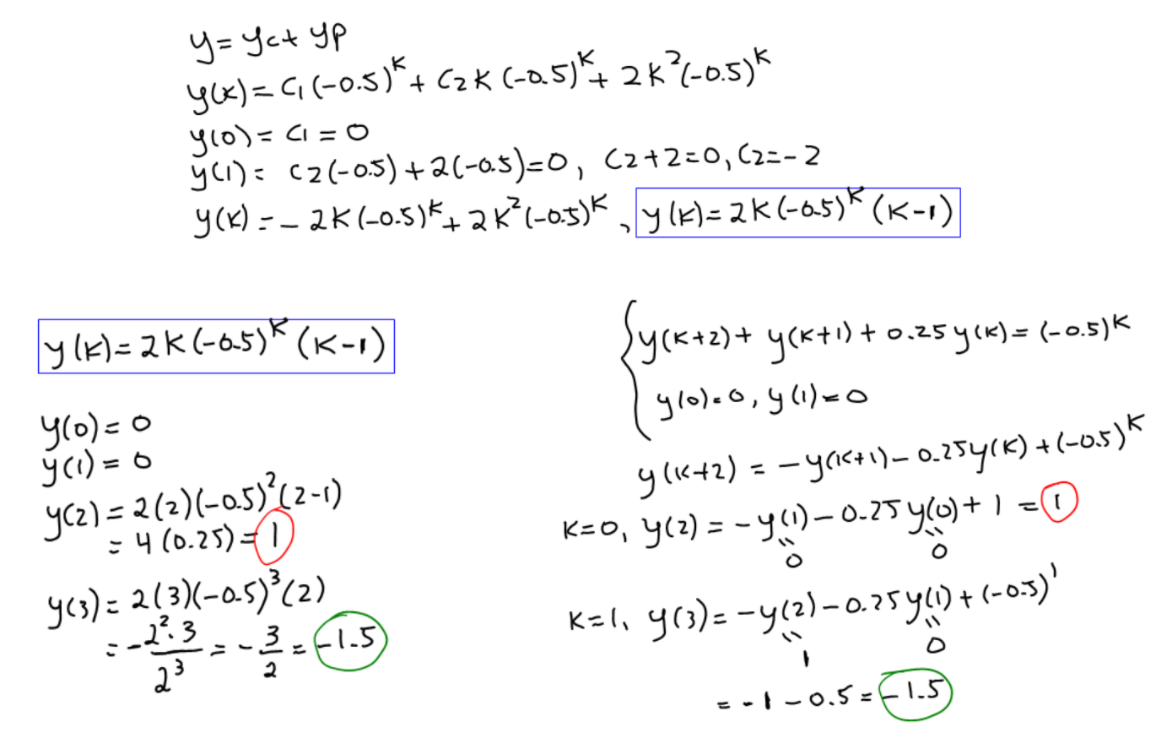

#### Segundo ejemplo de solución analítica: lambda imaginario

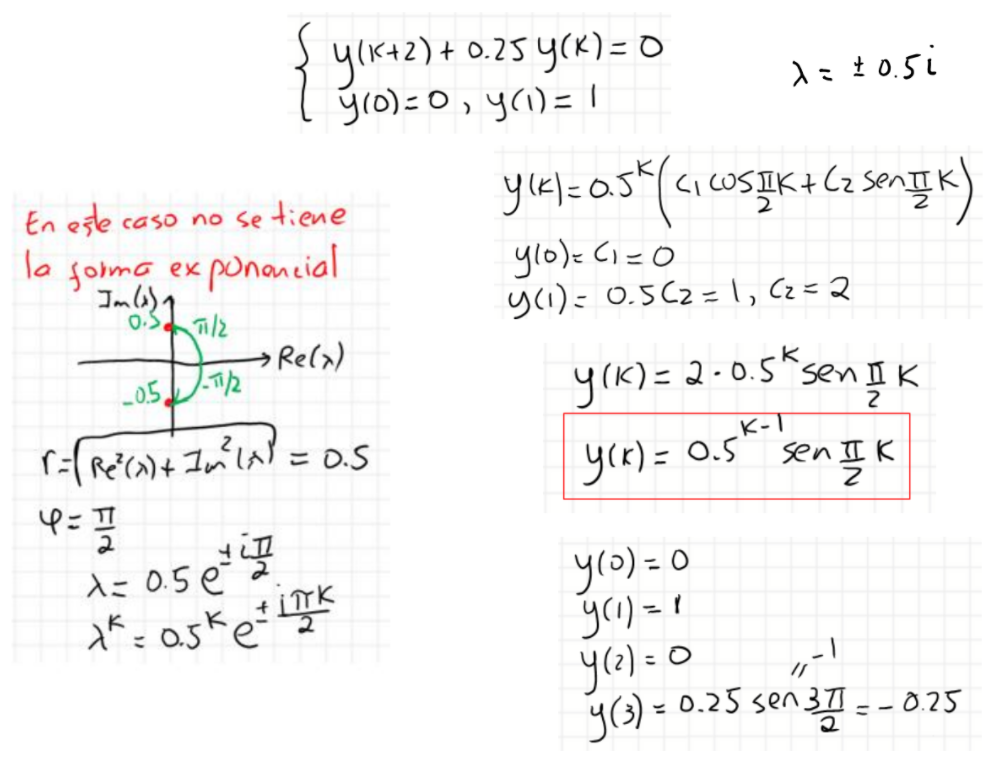

#### Tercer ejemplo de solución analítica: Ceros que no tienen sentido

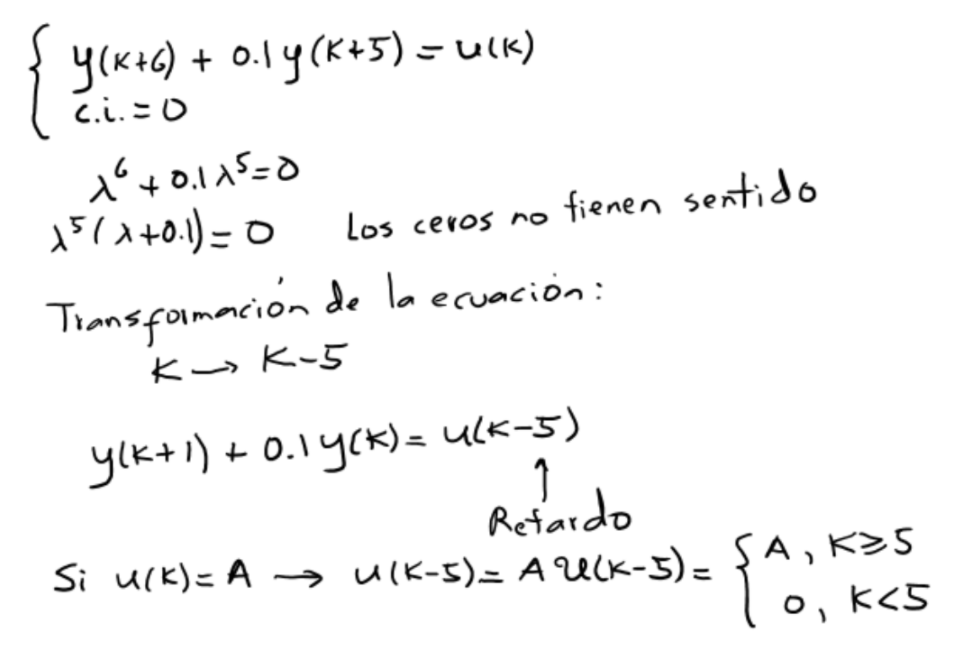

## Clase 4: Transformada de Laplace y transformada Z

### Definición: Transformada de Laplace


$$L\left\lbrace f\left(t\right)\right\rbrace \equiv \Im \left(s\right)=\int_{0^- }^{\infty } e^{-\mathrm{st}} f\left(t\right)\mathrm{dt},\;s=\sigma +i\omega$$


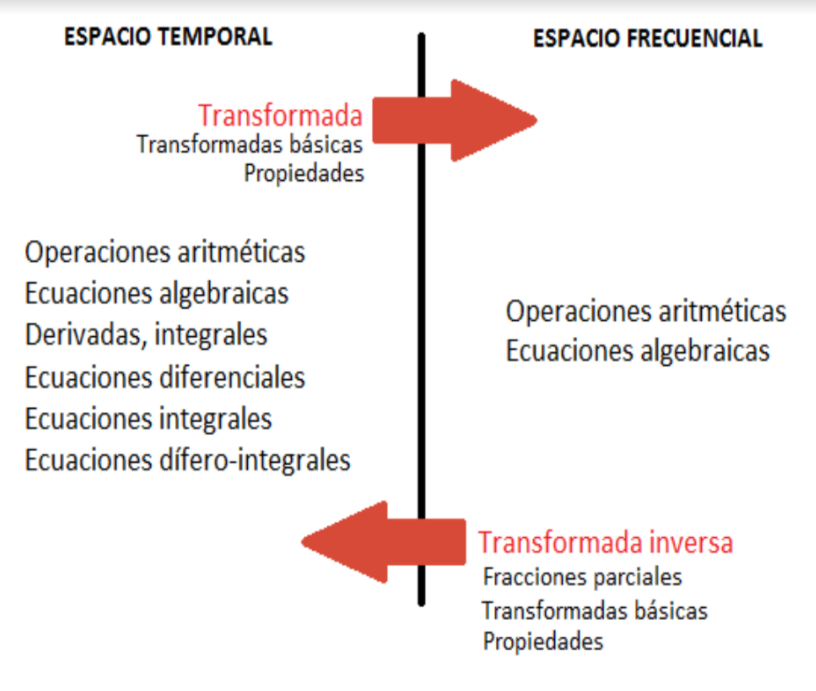

### Transformadas básicas transformada de Laplace

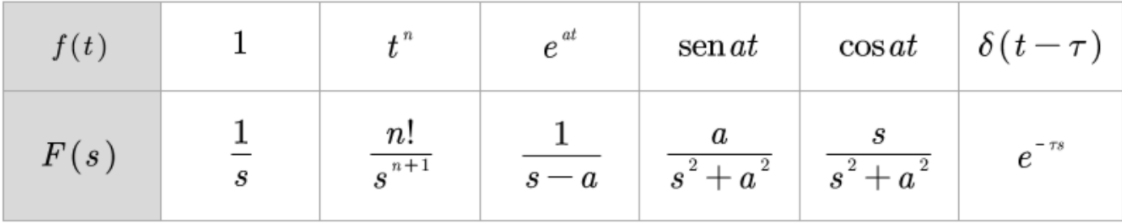

### Propiedades básicas transformada de Laplace